clear

# GPH 333 - Lab 6, Seismic Waves

Nate Crummett

### Importing PREM.xls

opts = spreadsheetImportOptions("NumVariables", 5);
opts.Sheet = "Sheet1";
opts.DataRange = "A2:E50";
opts.VariableNames = ["Depthbottomkm", "Vpms", "Vsms", "rhokgm3", "layer"];
opts.VariableTypes = ["double", "double", "double", "double", "string"];
opts = setvaropts(opts, "layer", "WhitespaceRule", "preserve");
opts = setvaropts(opts, "layer", "EmptyFieldRule", "auto");
PREM = readtable("C:\Users\rncru\Downloads\GPH333\Labs\PREM.xls", opts, "UseExcel", false);
clear opts
PREM{8:9,5} = ""; PREM{7,5} = "ASTENOSPHERE"; % cleaning up formatting manually

### Question 1

#### A)

Snell's law is


$$\frac{V_1 }{V_2 }=\frac{\sin \left(\theta_1 \right)}{\sin \left(\theta_2 \right)}$$


Thus for an increase in velocity ($V_2 >V_1$) we should see an increase in angle of incedence ($\theta_2 >\theta_1$). Using this relationship, it become clear that 


$$V_{2d} < V_{2c} < V_{2b} < V_{2a}$$


For rays *c *and *a*, the velocity $V_2$ can be determined exactly given the angle of incedence $\theta_1 ={40}^{\circ }$. At *a, *$\theta_{2} = 90^{\circ}$. And at *c*, $\theta_{2} = \theta_{1}$. These ovservations lead to the following conclusions 


$$\frac{V_{1a} }{V_{2a} }=\frac{\sin \left(\theta_1 \right)}{\sin \left(\theta_2 \right)}\;\;\;\;\;\textrm{given}\;\;\;\theta_1 ={40}^{\circ } \;,\;\;\theta_2 ={90}^{\circ } \;\;\;\to {\;\;V}_{1a} =0\ldotp 6428*V_{2a}$$



$$\frac{V_{1c} }{V_{2c} }=1\;\;\;\to {\;\;V}_{1c} =V_{2c}$$


#### B)

% insert image

#### C)

In the first layer $V_{1\;\left(p-\textrm{wave}\right)\;} =\;0\ldotp 6*V_{1\;\left(s-\textrm{wave}\right)}$, thus


$$V_{1\;\left(p-\textrm{wave}\right)} =5\;\;\to {\;\;V}_{1\;\left(s-\textrm{wave}\right)} =3$$


Now we can evaluate the velocity for ray *c.* Utilizing Snell's law


$$\frac{V_{\textrm{incoming}} }{V_{\textrm{outgoing}} }=\frac{\sin \left(\theta_{\textrm{incoming}} \right)}{\sin \left(\theta_{\textrm{outgoing}} \right)}\;\;\to \;\;\;\theta_{\textrm{outgoing}} =\sin^{-1} \left(\sin \left(\theta_{\textrm{incoming}} \right)*\frac{V_{\textrm{outgoing}} }{V_{\textrm{incoming}} }\right)$$


theta = round(asind(sind(40)*3/5),2,'decimals');
disp("The outgoing S-wave has an inclination of " + theta + " degrees from vertical")

The outgoing S-wave has an inclination of 22.69 degrees from vertical


clear theta
% insert image

### Question 2

% insert image

### Question 3

% dividing the table given into distinct layers
layer = PREM{:,5}; missingIDX = (layer == "");

% building array of index's of the top of each layer
layerCount = 1;
for i = 1:length(missingIDX)
    if ~missingIDX(i)
        layerList(layerCount,1) = i;
        layerCount = layerCount+1;
    end
end

% string array of layer names
layerNames = layer(layerList);

#### A)

The amount of time it takes for a p-wave to travel to the other side of the earth is the amount of time it takes to get to the core doubled.

To find the amount of time to get to the core, simply divide the distance traveld by the velocity of the p-wave. Like a crude integral type of idea.

% distance travelled for each velocity zone
depthToBottom = PREM.Depthbottomkm;
depthToTop = 0;
distance = ones(length(depthToBottom),1);

for i = 1:length(depthToBottom)
    distance(i) = depthToBottom(i) - depthToTop;
    depthToTop = depthToBottom(i);
end

% appending to table
PREM.Distance = distance;

% time to travel each velocity zone
time_s = (PREM.Distance*1000)./PREM.Vpms; % seconds - distances both converted to meters for calculation
PREM.TimePerLayer = time_s./60; % minutes
timeToCenter = sum(PREM.TimePerLayer); % time to get to the center of the earth in minutes
timeToOtherSide = timeToCenter*2;
secToOtherSide = rem(timeToOtherSide,1)*60;
minToOtherSide = timeToOtherSide - rem(timeToOtherSide,1);
disp("The time to get to the other side of the world is " + minToOtherSide + " minutes and " + round(secToOtherSide,0,'decimals') + " seconds long")

The time to get to the other side of the world is 18 minutes and 49 seconds long


The final depth in the table seems smaller than 6371 radius of Earth value I have seen before... not quite sure what to make of this.

#### B)

Plot depth (y increasing down) vs density, vpms, vsms

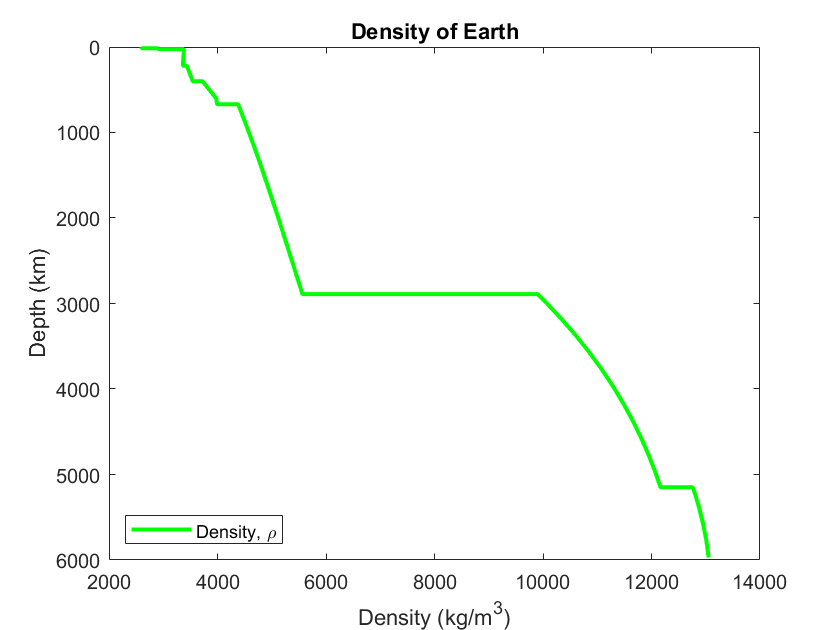

figure(1);
% density
plot(PREM.rhokgm3,PREM.Depthbottomkm,'g-','LineWidth',2)
set(gca,'YDir','reverse')
set(gca,'Box','on')
xlabel('Density (kg/m^3)'); ylabel ('Depth (km)');
title("Density of Earth");
legend("Density, \rho","Location","sw")
saveas(gcf,"Lab6_fig1.png")

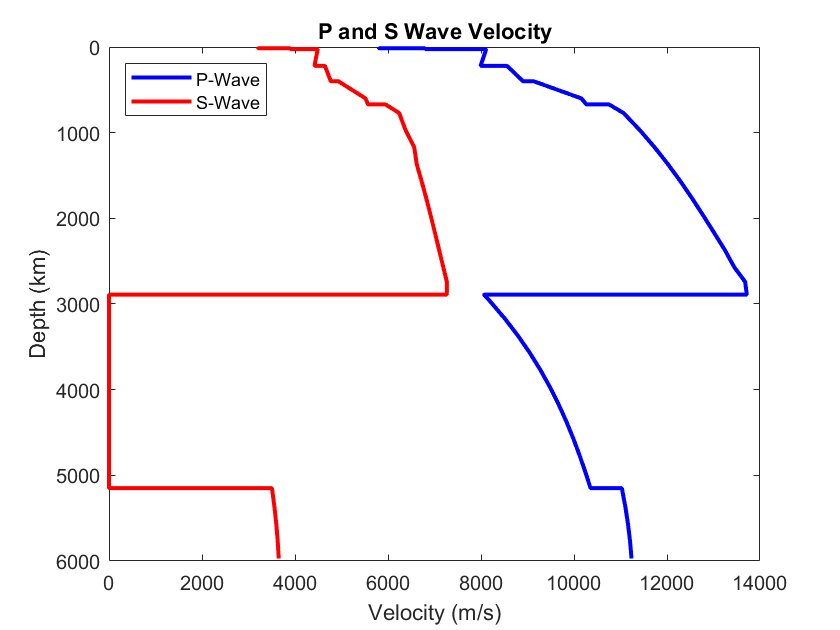

figure(2);
% velocity plots
hold on
plot(PREM.Vpms,PREM.Depthbottomkm,'LineWidth',2,'Color','b')
plot(PREM.Vsms,PREM.Depthbottomkm,'LineWidth',2,'Color','r')
hold off
set(gca,'YDir','reverse')
set(gca,'Box','on')
xlabel("Velocity (m/s)"); ylabel("Depth (km)");
legend('P-Wave','S-Wave','Location','nw')
title("P and S Wave Velocity");
saveas(gcf,"Lab6_fig2.png")

#### C)

P-wave and S-wave velocities are given respectively by


$$V_P =\sqrt{\frac{\;k+\left(4/3\right)*\mu }{\rho }}$$
           
$$V_S =\sqrt{\frac{\mu }{\rho }}$$


Rearranging the equation for shear wave velocity $V_S$, the shear modulus $\mu$ can be sovled for.


$$\mu \;\;=\;\;\rho *{\left(V_S \right)}^2$$


And bulk modulus $k$ can be solved for by substitution.


$$k\;=\;\rho *{\left(V_P \right)}^2 -\left(4/3\right)*\mu \;\;\;\to \;\;\;k\;=\;\rho *\left\lbrack {\left(V_P \right)}^2 \;-\;\left(4/3\right)*{\left(V_S \right)}^2 \right\rbrack$$


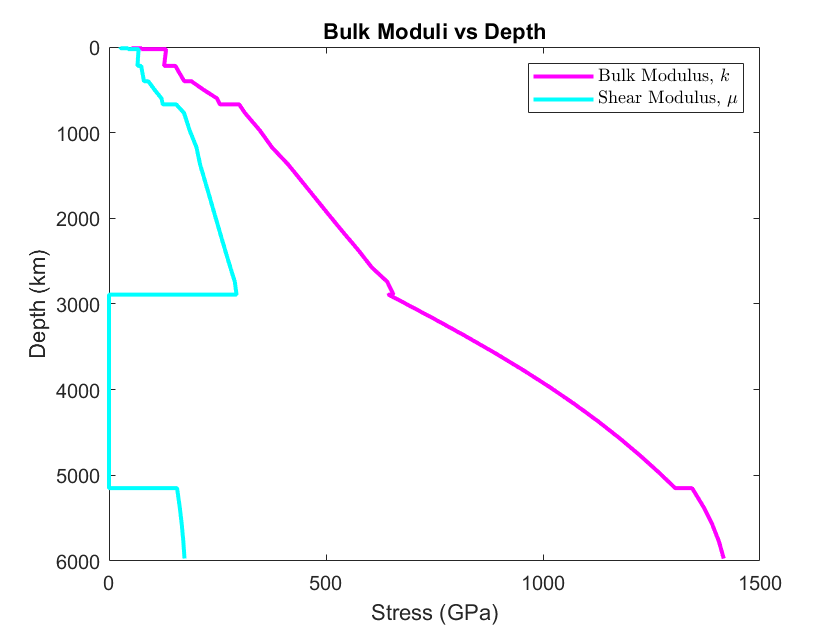

mu = PREM.rhokgm3 .* (PREM.Vsms).^2; % Pa
k = PREM.rhokgm3 .* ((PREM.Vpms).^2 - (4/3)*(PREM.Vsms).^2); % Pa
PREM.kGPa = k*10^(-9);
PREM.MuGPa = mu*10^(-9);
clear mu k
% bulk moduli
figure(3);
hold on
plot(PREM.kGPa,PREM.Depthbottomkm,'m','LineWidth',2)
plot(PREM.MuGPa,PREM.Depthbottomkm,'c','LineWidth',2)
hold off
set(gca,'YDir','reverse')
set(gca,'Box','on')
xlabel('Stress (GPa)'); ylabel("Depth (km)");
title("Bulk Moduli vs Depth");
legend("Bulk Modulus, $k$","Shear Modulus, $\mu$","Location","ne",'Interpreter','LaTeX')
saveas(gcf,"Lab6_fig3.png")

#### D)

"Dramatic change in both S- and P-wave across core-mantle boundary"

- This is a result of a phase change. The mantle is solid, while the outer core is liquid. Since liquids do not shear, the shear modulus $\mu$ instantly drops to zero, and the S-wave velocity also drops to zero.

"The interpretation that the inner core is solid"

- Since the S-wave velocity is non zero in the inner core, it must have a shear bulk modulus that is not zero. If the shear culk modulus is not zero, the inner core cannot be liquid. Thus, the inner core is a phase change to solid from the liquid phase of the inner core.

### Question 4

#### A)

distance = 2; % km
timeP = 0.4; % s
pWaveVelo = distance/timeP; % km/s
disp("The P-wave velocity in the top layer is " + pWaveVelo + " km/s")

The P-wave velocity in the top layer is 5 km/s


#### B)

k = 30; % GPa
density = 2.7; % g/cm^3

% conversion to SI units

distance = distance*1000; % m
k = k*10^9; % Pa
density = density/1000*100^3; % kg/m^3
pWaveVelo = pWaveVelo*1000; % m/s

The equation for P-wave velocity can be rearranged to solve for shear modulus $\mu$ in terms of density $\rho$, bulk modulus $k$, and P-wave velocity $V_P$ which was solved for above.


$$V_P =\sqrt{\frac{\;k+\left(4/3\right)*\mu }{\rho }}\;\;\to \;\;\mu \;=\;\frac{3}{4}\;*\left({\;\rho *\left(V_P \right)}^2 \;-k\;\right)$$


mu = (3/4)*(density*(pWaveVelo)^2 - k);
disp("The shear modulus of the top layer is " + mu*10^(-9) + " GPa")

The shear modulus of the top layer is 28.125 GPa


#### C)

sWaveVelo = sqrt(mu/density); % m/s
fraction = sWaveVelo/pWaveVelo;
disp("The S-wave/P-wave velocity ratio is " + fraction)

The S-wave/P-wave velocity ratio is 0.6455


#### D)

This is similar to part **A** but with the S-wave velocity given rather than time.

timeS = distance/sWaveVelo;
disp("The S-wave takes " + timeS + " seconds to arrive at the geophone")

The S-wave takes 0.61968 seconds to arrive at the geophone


#### E)

The velocity of the P-wave is known. The distance from the source is known (0 m). Given the time (0.6 s), solving distance travelled is possible - and depth is just half of that for the current set up.

timeVertRef = 0.6; % s
distanceVertRef = pWaveVelo*timeVertRef; % m
depthVertRef = distanceVertRef/2; % m
disp("The first layer is " + depthVertRef/1000 + " km thick") % km

The first layer is 1.5 km thick


#### F)

Now the geophone is 2000 m away. Since depth is known, the time for the first reflection to arrive at the geophone is just a trigonometry problem - the reflection bisects the distance to the first geophone ( ie @ 1000 m).

distHorRef = distance/2; % m
r = sqrt(depthVertRef^2 + distHorRef^2); % m
timeRef = (2*r)/pWaveVelo; % s
disp("The first reflection takes " + round(timeRef,3,'decimals') + " seconds to reach the geophone")

The first reflection takes 0.721 seconds to reach the geophone


#### G)

% insert image
distSame = sqrt(depthVertRef^2/((pWaveVelo/(2*sWaveVelo))^2 - (1/4))); % m
disp("The distance where the arrival times will be the same is " + round(distSame/1000,2,'decimals') + " km from the source")

The distance where the arrival times will be the same is 2.54 km from the source


#### H)

% insert image

The wave speed differences in each layer control the angles of incedence. This is just a restatement of Snell's law.


$$\frac{\sin \left(\theta_{i,P} \right)}{V_P }\;=\;\;\frac{\sin \left(\theta_{r,P} \right)}{V_P }\;=\;\frac{\sin \left(\theta_{r,S} \right)}{V_S }$$


The velocities of the reflected waves are known. Since the reflected P-wave's velocity does not change (it is obviously still in the first layer if it reflects), the angle of incedence of the incomming P-wave is equal to the angle of reflection of the P-wave. So, first the angle of incedence needs to be calculated.

theta_i = atand(distHorRef/depthVertRef);
disp("The angle of incedence is " + round(theta_i,2,'decimals') + " degrees from vertical")

The angle of incedence is 33.69 degrees from vertical


Now that this is solved for, $\theta_{r,S}$ can be solved for.

theta_rS = asind(fraction*sin(theta_i));
disp("The angle of reflection for the S-wave is " + round(theta_rS,2,'decimals') + " degrees from vertical")

The angle of reflection for the S-wave is 29.49 degrees from vertical


Now trigonometry will allow for a calculation of X, distance from the reflected S-wave reflects to.

X = distHorRef + tand(theta_rS)*depthVertRef;
disp("The distanace from the geophone the reflected S-wave arrives at is " + round(X/1000,2,'decimals') + " km")

The distanace from the geophone the reflected S-wave arrives at is 1.85 km


### Bonus

#### 1)

% insert image

Exit angle ($\theta_{C}$) is the same as incidence angle ($\theta_{C}$) because $V_0$ does not change. 

Time can be computed by dividing the distance by velocity. Since velocities for each region are known, distance needs to be worked out. This is actually pretty neat, took me a second to see the last two steps

% image image

#### 2)

I aready derived the time equation above. Rearranging it leads to


$$t\;=\;\frac{x}{V_1 }\;-\;\frac{2*h*\cos \left(\theta_C \right)}{V_0 }\;\;\;\to \;\;\;x\;=V_1 *\left(t\;+\;\frac{2*h*\cos \left(\theta_C \right)}{V_0 }\right)$$
 

As before, $sin(\theta_C) = V_0/V_1$


$$x\;=V_1 *t\;+\;\frac{2*h*V_1 *\cos \left(\theta_C \right)}{V_0 }\;\;\;\to \;\;\;x\;={\;V}_1 *t\;+\;\frac{2*h*\cos \left(\theta_C \right)}{\sin \left(\theta_C \right)}$$



$$x\;={\;V}_1 *t\;+\;\frac{2*h*\cos \left(\theta_C \right)}{\sin \left(\theta_C \right)}\;\;\;\;\to \;\;\;x\;={\;V}_1 *t\;+\;\frac{2*h}{\tan \left(\theta_C \right)}$$


Now I can solve for minimum $x$. Since time cannot be negative, and $V_1$ is positive, minimum distance is when $t = 0$


$$x_{\textrm{minimum}} \;\;=\;\frac{2*h}{\tan \left(\theta_C \right)}$$
